# Homework 2

Alberto Anaya Gallego: 100471718

Cristina Mallor Franco: 100471699  

clear; clc; close all;

The purpose of this third homework is to study the maneuvers required to place a chaser vehicle at a certain distance from the Chinese Tiangong space station located on a circular orbit at 390 km of altitude. 

## Data of the problem

First, a two-impulsive maneuver will be studied to obtain its Delta-V cost, for a chaser with a relative initial position of y = -1km and a final relative position of y = -100 m, in the Hill's reference frame. The data provided in the statement of the problem is written below.

mu = 398600; % Earth gravitational parameter (km^3/s^2)
h_t =  390; % Tiangong space station height (km)
RE = 6371; % Earth radius (km)
rh = h_t + RE; % Space station distance from the center of the Earth (km)

% Initial conditions
% relative position
r0 = [0; -1; 0]; % km

% Final condition
% relative position
rf = [0; -0.1; 0]; % km

% Time of maneuver
n = sqrt(mu/rh^3); % mean angular rate rad/s
tau = 2*pi/n; % Tiangong's orbital period (s)
t = tau/2; % time of maneuver (s)

## a.) Compute the two-impulse maneuver for the hop using the simplified CW equations

The function 'hopping' takes in as inputs the omega, which corresponds to the mean angular rate of the Tiangong's orbit around Earth expressed in rad/s, and Deltay which represents the increment in position along the V-direction (y) in meters; and gives as an output the vector cost of each impulse in m/s.

omega = n;
Deltay = (rf(2)-r0(2))*1000; %m
[DV1,DV2]=hopping(omega, Deltay);


% Print the vectors and their respective magnitudes
fprintf('Delta-V1 vector: [%f, %f, %f] m/s\n', DV1(1), DV1(2), DV1(3));

Delta-V1 vector: [-0.255526, 0.000000, 0.000000] m/s


fprintf('Magnitude of Delta-V1: %f m/s\n', norm(DV1));

Magnitude of Delta-V1: 0.255526 m/s



fprintf('Delta-V2 vector: [%f, %f, %f] m/s\n', DV2(1), DV2(2), DV2(3));

Delta-V2 vector: [-0.255526, -0.000000, 0.000000] m/s


fprintf('Magnitude of Delta-V2: %f m/s\n', norm(DV2));

Magnitude of Delta-V2: 0.255526 m/s


Examining the results provided by the *hopping* function, it can be observed that both cost values are identical. This is due to the fact that, at the initial instant, both bodies have zero relative velocity. To position the chaser at a closest point, it must first leave its established orbit by executing a maneuver that propels it to the left in the Hill's reference frame, therefore the the R component of the Delta-V vector is < 0. Subsequently, a second maneuver is required to return the chaser to its original orbit. Without this second maneuver, the chaser would remain in an intermediate orbit, which will be analyzed in subsequent sections.

## b.) Plotting different trajectories

In this section the trajectory of the chaser is represented for two different time spans.

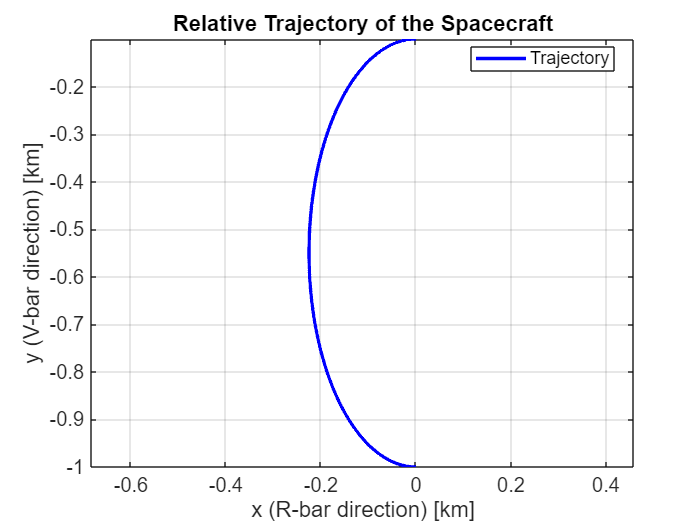

% 1. Half orbital period
t_vector1 = linspace(0, tau/2, 1000); % time vector (s)

for i = 1:length(t_vector1)
    t = t_vector1(i); % time (s)
    PHI=CW_TransMat(omega,t); % compute the CW matrices
    Phi_rr = PHI(1:3,1:3); % position-to-position state transition matrix
    Phi_rv = PHI(1:3,4:6); % position-to-velocity state transition matrix
    r1(:,i) = Phi_rr*r0 + Phi_rv*DV1/1000; % compute the relative position (km)
end


figure;
plot(r1(1,:),r1(2,:),'b','LineWidth',2); % plot the trajectory
xlabel('x (R-bar direction) [km]');
ylabel('y (V-bar direction) [km]');
title('Relative Trajectory of the Spacecraft');
grid on;
axis equal;
set(gca, 'FontSize', 12, 'FontName', 'Arial');
legend('Trajectory', 'Location', 'best');

The figure above illustrates the chaser's trajectory over half of Tiangong's orbital period. It shows how the chaser moves to the left, hence the negative ΔV, ultimately reaching a final position at a distance of *y* = –100 m.

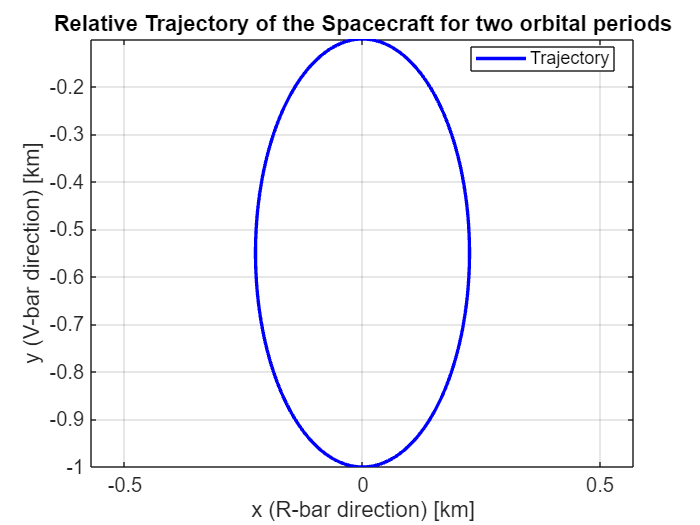


% 2. Two orbital period
t_vector2 = linspace(0, 2*tau, 2000); % time vector 2 (s) 

for i = 1:length(t_vector2)
    t = t_vector2(i); % time (s)
    PHI=CW_TransMat(omega,t); % compute the CW matrices
    Phi_rr = PHI(1:3,1:3); % position-to-position state transition matrix
    Phi_rv = PHI(1:3,4:6); % position-to-velocity state transition matrix
    r2(:,i) = Phi_rr*r0 + Phi_rv*DV1/1000; % compute the relative position (km)
end

figure;
plot(r2(1,:),r2(2,:),'b','LineWidth',2); % plot the trajectory
xlabel('x (R-bar direction) [km]');
ylabel('y (V-bar direction) [km]');
title('Relative Trajectory of the Spacecraft for two orbital periods');
grid on;
axis equal;
set(gca, 'FontSize', 12, 'FontName', 'Arial');
legend('Trajectory', 'Location', 'best');

In the previous trajectory graph, only half a period was represented. Nevertheless, for this case two full orbital periods without performing the second maneuver will be illustrated. This is useful to prove that the chaser when only performing a single maneuver, remains in the intermediate orbit.

## c.) Montecarlo Anaylisis:

Now, a montecarlo analysis is conducted to take into account initial position errors, in this case of 1%.

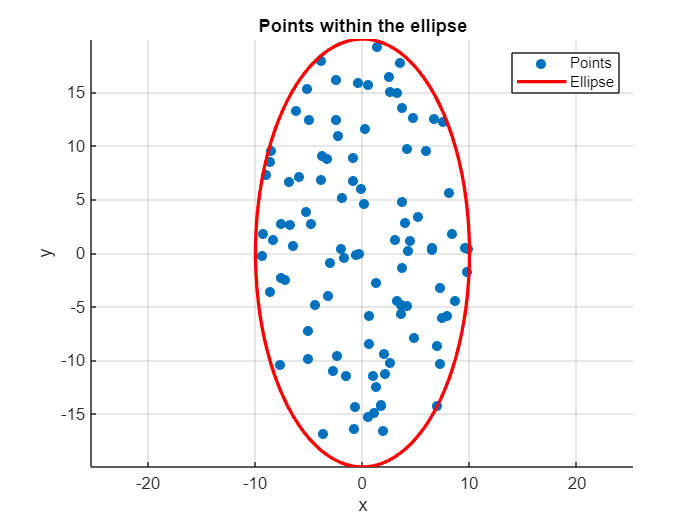

%Limits for the deviation in the ellipse: parameters sigma_x and sigmay
%define the limit of the ellipse in which random values will be taken. 
sigma_x = 10; 
sigma_y = 20; 
N = 100; %Number of samples

[x0, y0] = gaussDisp(sigma_x, sigma_y, N); %Computation of the random points, x0 and y0 are given in meters 

r0_vector = r0 + [x0; y0; zeros(1, length(x0))]/1000; %Dividing by 1000, as the vector is given in meters

The figure above represents the boundary of the initial position, defined as an ellipse. For the analysis, 100 randomly generated initial positions, normally distributed within this boundary, will be considered.

## d.) Compute and plot trajectories for all initial positions

The 100 random positions selected above, will be used to compute the trajectory of the chaser for the two impulsive maneuvers.

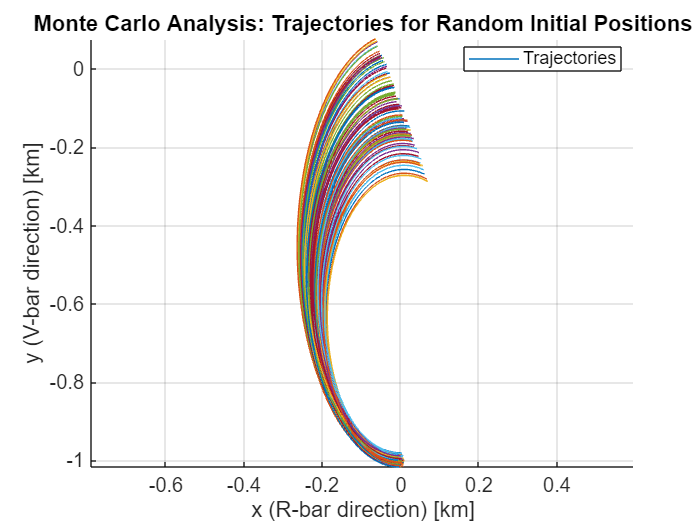

figure;
hold on;
for j = 1:N
    r0_sample = r0_vector(:, j); % Select a random initial position
    for i = 1:length(t_vector1)
        t = t_vector1(i); % time (s)
        PHI = CW_TransMat(omega, t); % compute the CW matrices
        Phi_rr = PHI(1:3, 1:3); % position-to-position state transition matrix
        Phi_rv = PHI(1:3, 4:6); % position-to-velocity state transition matrix
        r_sample(:, i) = Phi_rr * r0_sample + Phi_rv * DV1 / 1000; % compute the relative position (km)
    end
    plot(r_sample(1, :), r_sample(2, :)); % plot the trajectory
    
end
xlabel('x (R-bar direction) [km]');
ylabel('y (V-bar direction) [km]');
title('Monte Carlo Analysis: Trajectories for Random Initial Positions');
grid on;
axis equal;
set(gca, 'FontSize', 12, 'FontName', 'Arial');
legend('Trajectories', 'Location', 'best');
hold off;

This graph shows the 100 different trajectories that the orbit could have followed.

## e.)

In this section, the worst case trajectory will be selected. In order to fix this trajectory a mid course manouvre will be performed in order to correct the trajectory of the chaser such that the final position still remain as desired. 

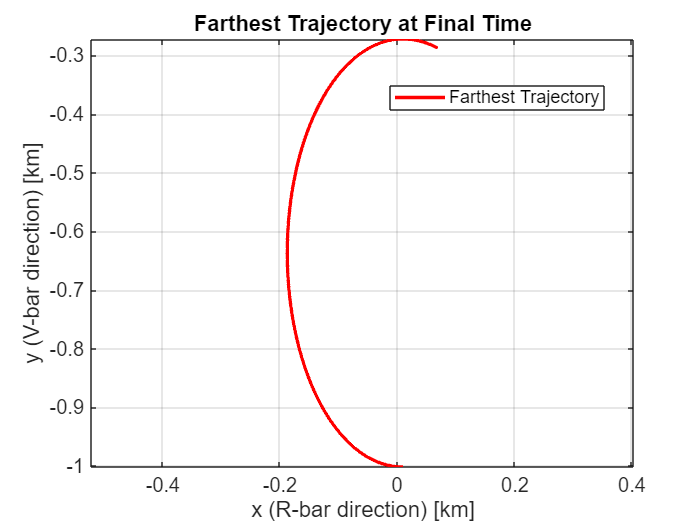

max_distance = 0;
farthest_trajectory = [];

for j = 1:N
    r0_sample = r0_vector(:, j); % Select a random initial position
    for i = 1:length(t_vector1)
        t = t_vector1(i); % time (s)
        PHI = CW_TransMat(omega, t); % compute the CW matrices
        Phi_rr = PHI(1:3, 1:3); % position-to-position state transition matrix
        Phi_rv = PHI(1:3, 4:6); % position-to-velocity state transition matrix
        r_sample(:, i) = Phi_rr * r0_sample + Phi_rv * DV1 / 1000; % compute the relative position (km)
    end
    % Compute the distance from the final point rf at the final time
    final_distance = norm(r_sample(:, end) - rf);

    if final_distance > max_distance
        max_distance = final_distance;
        r_far = r_sample; % Update the farthest trajectory
        r0_far = r0_sample; % Save the initial conditions for the farthest trajectory
    end

end



% Plot the farthest trajectory
figure;
plot(r_far(1, :), r_far(2, :), 'r', 'LineWidth', 2);
xlabel('x (R-bar direction) [km]');
ylabel('y (V-bar direction) [km]');
title('Farthest Trajectory at Final Time');
grid on;
axis equal;
set(gca, 'FontSize', 12, 'FontName', 'Arial');
legend('Farthest Trajectory', 'Location', 'best');

In order to select the required trajectory, the difference between the final point of each of the different trajectories and the desired final point is computed. That with higher difference is selected. In the upper figure, a plot of the worst trajectory is displayed. What follows is the evaluation of the position and velocity at the mid course of the trajectory, i.e. at a quarter of the orbital period. 


%Computation of the position at the midspan of the period of the orbit: 
t_midspan = tau/4; % time at midspan (s)
PHI_midspan = CW_TransMat(omega, t_midspan); % compute the CW matrices

Phi_rr_midspan = PHI_midspan(1:3, 1:3); % position-to-position state transition matrix
Phi_rv_midspan = PHI_midspan(1:3, 4:6); % position-to-velocity state transition matrix
Phi_vr_midspan = PHI_midspan(4:6, 1:3); % velocity-to-position state transition matrix
Phi_vv_midspan = PHI_midspan(4:6, 4:6); % velocity-to-velocity state transition matrix

r0_midspan = Phi_rr_midspan * r0_far + Phi_rv_midspan * DV1 / 1000; % compute the relative position (km)
v0_midspan = Phi_vr_midspan * r0_far + Phi_vv_midspan * DV1 / 1000; % compute the relative velocity (km/s)

Once the initial position of the 'new' trajectory has been computed, the state vector is created and introduced into the funtion mid_course, which returns the deltaVx and deltaVy required for the manouvre. Finallty, once the deltaV has been determined, the trajectory of the object can be easily computed. 

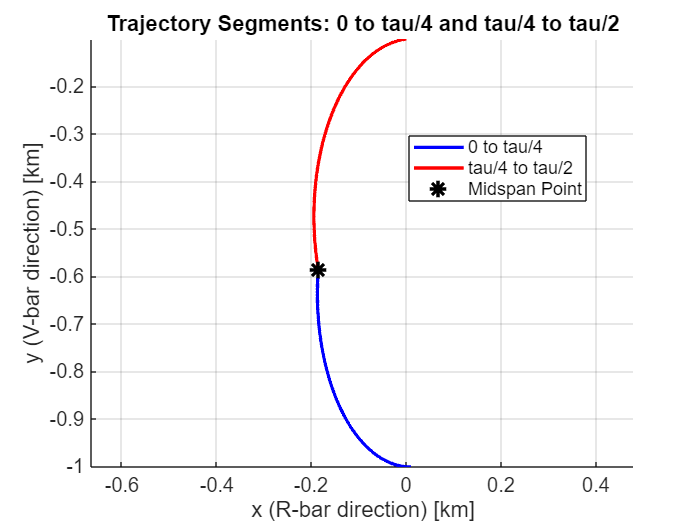


%Initial Conditions at a quarter of the orbit: 
r0 = r0_midspan; 
v0 = v0_midspan; 

%Final Conditions: 
rf = [0; -0.1; 0] * 1000; % in meters

%Creation of the state vector: 
state0MC = [r0_midspan, v0_midspan]; % state vector (km, km/s)

[DVx_midspan, DVy_midspan] = mid_course(omega, state0MC, rf);

DV1_midspan = [DVx_midspan; DVy_midspan; 0]; 


% Plot the trajectory from 0 to tau/4
t_vector_mid1 = linspace(0, tau/4, 500); % time vector (s)
trajectory_mid1 = zeros(3, length(t_vector_mid1));

for i = 1:length(t_vector_mid1)
    t = t_vector_mid1(i); % time (s)
    PHI = CW_TransMat(omega, t); % compute the CW matrices
    Phi_rr = PHI(1:3, 1:3); % position-to-position state transition matrix
    Phi_rv = PHI(1:3, 4:6); % position-to-velocity state transition matrix
    trajectory_mid1(:, i) = Phi_rr * r0_far + Phi_rv * DV1 / 1000; % compute the relative position (km)
end

% Plot the trajectory from tau/4 to tau/2
t_vector_mid2 = linspace(0, tau/4, 500); % time vector (s)
trajectory_mid2 = zeros(3, length(t_vector_mid2));

for i = 1:length(t_vector_mid2)
    t = t_vector_mid2(i); % time (s)
    PHI = CW_TransMat(omega, t); % compute the CW matrices
    Phi_rr = PHI(1:3, 1:3); % position-to-position state transition matrix
    Phi_rv = PHI(1:3, 4:6); % position-to-velocity state transition matrix
    trajectory_mid2(:, i) = Phi_rr * r0_midspan + Phi_rv * ((DV1_midspan)/1000 + v0_midspan); % compute the relative position (km)
end

% Plot both segments
figure;
hold on;
plot(trajectory_mid1(1, :), trajectory_mid1(2, :), 'b', 'LineWidth', 2); % 0 to tau/4
plot(trajectory_mid2(1, :), trajectory_mid2(2, :), 'r', 'LineWidth', 2); % tau/4 to tau/2

% Mark the midspan point with an asterisk
midspan_point = trajectory_mid1(:, end); % The end of the first trajectory is the midspan
plot(midspan_point(1), midspan_point(2), 'k*', 'MarkerSize', 10, 'LineWidth', 2);

xlabel('x (R-bar direction) [km]');
ylabel('y (V-bar direction) [km]');
title('Trajectory Segments: 0 to tau/4 and tau/4 to tau/2');
grid on;
axis equal;
set(gca, 'FontSize', 12, 'FontName', 'Arial');
legend('0 to tau/4', 'tau/4 to tau/2', 'Midspan Point', 'Location', 'best');
hold off;

The complete trajectory followed by the object is shown in the figure above. Initially, the nominal path, with its respective initial error, is followed; however, upon reaching the midpoint, the object may execute one of two possible manoeuvres depending on the initial error. If the initial error causes the trajectory to overshoot the desired point, the object will perform a ∆V manoeuvre with a positive ∆Vₓ component. Conversely, if the initial error results in an undershoot of the target point, the ∆Vₓ component will be negative.

### FUNCTIONS

Hopping function, computes the $\Delta V_1 $required to place the object at the desired point after half the orbital period. And $\Delta V_2$ required to perform the manouvre to keep at rest at the target final position. 

function [DV1,DV2]=hopping(omega,Deltay)

    % Inputs:
    % omega - orbit mean angular rate (rad/s); aka 'n'
    % Deltay - change in y position (m)
    
    % Outputs:
    % DV1 - first impulse velocity change (m/s)
    % DV2 - second impulse velocity change (m/s)

    %% Data

    % Relative motion parameters
    % Initial relative position
    r0 = [0; -1; 0]; % km
    % Final relative position
    rf = r0 + [0; Deltay; 0] /1000; % km

    % Time of maneuver
    n = omega; % mean angular rate rad/s
    tau = 2*pi/n; % Tiangong's orbital period (s)
    t = tau/2; % time of maneuver (s)

    
    %% Algorithm
    % 1. Determination of the CW matrices
    [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = CW_matrices(n, t);

    % 2. Initial velocity after the first impulse
    v0_plus = inv(Phi_rv)*(rf-Phi_rr*r0);

    % 3. Final velocity before the second impulse
    vf_minus = Phi_vr*r0 + Phi_vv*v0_plus;

    % 4. Initial velocity before first impulse
    v0_minus = zeros(3,1); % km/s; zeros since both the chaser and target are initially in the same circular orbit

    % 5. Final velocity after the second impulse
    vF_plus = zeros(3,1); % km/s; zeros since both the chaser and target are at the end in the same circular orbit

    % 6. Velocity change for the first impulse
    DV1 = (v0_plus - v0_minus) * 1000; % m/s


    % 7. Velocity change for the second impulse
    DV2 = (vF_plus - vf_minus) * 1000; % m/s



    function [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = CW_matrices(n, t)
        
        % Inputs:
        %   n - Mean motion (rad/s)
        %   t - Time (s)

        % Outputs:
        %   Phi_rr - Position-to-position state transition matrix
        %   Phi_rv - Position-to-velocity state transition matrix
        %   Phi_vr - Velocity-to-position state transition matrix
        %   Phi_vv - Velocity-to-velocity state transition matrix
    
        % Position-to-position transition matrix (Phi_rr)
        Phi_rr = [4 - 3*cos(n*t), 0, 0;
                  6*(sin(n*t) - n*t), 1, 0;
                  0, 0, cos(n*t)];
    
        % Position-to-velocity transition matrix (Phi_rv)
        Phi_rv = [1/n*sin(n*t), 2/n*(1 - cos(n*t)), 0;
                  2/n*(cos(n*t) - 1), 1/n*(4*sin(n*t) - 3*n*t), 0;
                  0, 0, 1/n*sin(n*t)];
    
        % Velocity-to-position transition matrix (Phi_vr)
        Phi_vr = [3*n*sin(n*t), 0, 0;
                  6*n*(cos(n*t) - 1), 0, 0;
                  0, 0, -n*sin(n*t)];
    
        % Velocity-to-velocity transition matrix (Phi_vv)
        Phi_vv = [cos(n*t), 2*sin(n*t), 0;
                  -2*sin(n*t), 4*cos(n*t) - 3, 0;
                  0, 0, cos(n*t)];
    end

end

#### **CW_TransMat function: **

function PHI=CW_TransMat(omega,t)

    % Inputs:
        %   omega - Mean motion (rad/s)
        %   t - Time (s)

        % Outputs:
        %   Phi_rr - Position-to-position state transition matrix
        %   Phi_rv - Position-to-velocity state transition matrix
        %   Phi_vr - Velocity-to-position state transition matrix
        %   Phi_vv - Velocity-to-velocity state transition matrix

        n = omega;

        % Position-to-position transition matrix (Phi_rr)
        Phi_rr = [4 - 3*cos(n*t), 0, 0;
                  6*(sin(n*t) - n*t), 1, 0;
                  0, 0, cos(n*t)];
    
        % Position-to-velocity transition matrix (Phi_rv)
        Phi_rv = [1/n*sin(n*t), 2/n*(1 - cos(n*t)), 0;
                  2/n*(cos(n*t) - 1), 1/n*(4*sin(n*t) - 3*n*t), 0;
                  0, 0, 1/n*sin(n*t)];
    
        % Velocity-to-position transition matrix (Phi_vr)
        Phi_vr = [3*n*sin(n*t), 0, 0;
                  6*n*(cos(n*t) - 1), 0, 0;
                  0, 0, -n*sin(n*t)];
    
        % Velocity-to-velocity transition matrix (Phi_vv)
        Phi_vv = [cos(n*t), 2*sin(n*t), 0;
                  -2*sin(n*t), 4*cos(n*t) - 3, 0;
                  0, 0, cos(n*t)];

        PHI = [Phi_rr Phi_rv; Phi_vr Phi_vv];




end



#### **Gauss Dispersion function: **

function [x_in, y_in] = gaussDisp(sigma_x, sigma_y, N)

% Generate N random points inside the ellipse
x_in = [];
y_in = [];

while length(x_in) < N
    % Generate random points within the bounds of the ellipse
    x0 = -sigma_x + 2 * sigma_x * rand; % Uniform distribution in [-sigma_x, sigma_x]
    y0 = -sigma_y + 2 * sigma_y * rand; % Uniform distribution in [-sigma_y, sigma_y]
    
    % Check if the point lies within the ellipse
    if (x0^2 / sigma_x^2 + y0^2 / sigma_y^2) <= 1
        x_in = [x_in, x0];
        y_in = [y_in, y0];
    end
end

figure; 
% Display the points inside the ellipse
scatter(x_in, y_in, 'filled');
xlabel('x');
ylabel('y');
title('Points within the ellipse');
axis equal;
grid on;

% Plot the ellipse boundary
theta = linspace(0, 2*pi, 100);
ellipse_x = sigma_x * cos(theta);
ellipse_y = sigma_y * sin(theta);
hold on;
plot(ellipse_x, ellipse_y, 'r', 'LineWidth', 2);
legend('Points', 'Ellipse');
hold off;



end 

#### **Mid Course function: **

function [DVx, DVy] = mid_course(omega,state0MC,rf)

    %Inputs: 
    % omega: mean angular rate (rad/s)
    % state0MC: mid course state vector (position and velocity) of the chaser (km, km/s)
    % rf: final relative position (km)

    %Outputs: 
    % DVx: Delta velocity change in x direction (m/s)
    % DVy: Delta velocity change in y direction (m/s)

     % Time of maneuver
    n = omega; % mean angular rate rad/s
    tau = 2*pi/n; % Tiangong's orbital period (s)
    t = tau/4; % time of maneuver (s)
    
    rf = rf/1000; %Change from meters to kilometers. 

    %1.) 
    r0_midspan = state0MC(1:3, 1); % initial position (km)
    v0_midspan = state0MC(1:3, 2); % initial velocity (km/s)

    % 2. Determination of the CW matrices
    [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = CW_matrices(omega, t); % compute the CW matrices %Duda, que tiempo pongo 0 o tau/4?

    % 3. Initial velocity after the first impulse
    v0_plus = inv(Phi_rv)*(rf-Phi_rr*r0_midspan);

    % 4. Final velocity before the second impulse
    vf_minus = Phi_vr*r0_midspan + Phi_vv*v0_plus;

    % 5. Initial velocity before first impulse
    v0_minus = v0_midspan; % km/s; zeros since both the chaser and target are initially in the same circular orbit

    % 7. Final velocity after the second impulse
    vF_plus = zeros(3,1); % km/s; zeros since both the chaser and target are at the end in the same circular orbit

    % 8. Velocity change for the first impulse
    DV1 = (v0_plus - v0_minus) * 1000; % m/s
    DVx = DV1(1); 
    DVy = DV1(2); 


    function [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = CW_matrices(n, t)
        
        % Inputs:
        %   n - Mean motion (rad/s)
        %   t - Time (s)

        % Outputs:
        %   Phi_rr - Position-to-position state transition matrix
        %   Phi_rv - Position-to-velocity state transition matrix
        %   Phi_vr - Velocity-to-position state transition matrix
        %   Phi_vv - Velocity-to-velocity state transition matrix
    
        % Position-to-position transition matrix (Phi_rr)
        Phi_rr = [4 - 3*cos(n*t), 0, 0;
                  6*(sin(n*t) - n*t), 1, 0;
                  0, 0, cos(n*t)];
    
        % Position-to-velocity transition matrix (Phi_rv)
        Phi_rv = [1/n*sin(n*t), 2/n*(1 - cos(n*t)), 0;
                  2/n*(cos(n*t) - 1), 1/n*(4*sin(n*t) - 3*n*t), 0;
                  0, 0, 1/n*sin(n*t)];
    
        % Velocity-to-position transition matrix (Phi_vr)
        Phi_vr = [3*n*sin(n*t), 0, 0;
                  6*n*(cos(n*t) - 1), 0, 0;
                  0, 0, -n*sin(n*t)];
    
        % Velocity-to-velocity transition matrix (Phi_vv)
        Phi_vv = [cos(n*t), 2*sin(n*t), 0;
                  -2*sin(n*t), 4*cos(n*t) - 3, 0;
                  0, 0, cos(n*t)];
    end




end 